%Definizioni
velocita_seriale= 1000000; 
seriali_disponibili = serialportlist('available');
if( exist('ser') ) 
    delete(ser);
    clear ser;
end

seriale_micro= seriali_disponibili(end);
ser = serialport(seriale_micro, velocita_seriale,Timeout=10); 
configureTerminator(ser,"CR");

%con codice MATLAB era possibile un'altra implementazione
%MATLAB avrebbe guà ricevuto il vettore completo di misure
numero_forme_onda = 10000; %totale nuemro campionamenti
numero_punti_forme_onda = 100; %punti per forma d'onda
maschera = [5,20]; %maschera per massimo
massimi = zeros(1,numero_forme_onda); %ettore massimi
figure;
hold on; %plottare tutto su uno stesso plot
for i = 1:numero_forme_onda %campionamento
    while true 
        ser.flush;
        stringa= "w";
        ser.writeline(stringa);
        misure = ser.read(numero_punti_forme_onda, "uint16");
        pretrigger = ser.read(1, "uint16");
        misure = (misure ./ (2^16 - 1))*3.3;
        t = numero_punti_forme_onda  - pretrigger;
        misure = circshift(misure, -t-1);
        if mean(misure) < 1 %togliere misure errate
            break
        end
    end
    restrizione = misure(maschera(1):maschera(2)); %applicazione maschera
    massimi(i) = max(restrizione); %massimo
    %plot(restrizione);
end
hold off;
disp('Fine') %conclusione

Fine


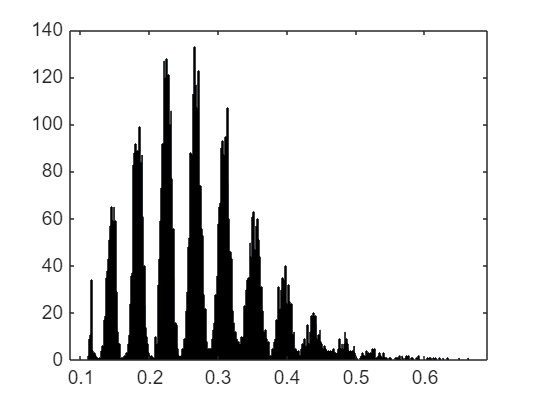

histogram(massimi, 500)

delete(ser)
clear("ser")


